# Rozwiązywania układu równań **nieliniowych**. 

**Celem ćwiczenia: **jest obliczenie układu równań nieliniowych i reprezentacja graficzna rozwiązania. 

Wykorzystany zostanie  Symbolic Math Toolbox, który wykorzystywany jest gdy potrzebne są dokładne, analityczne rozwiązania matematyczne. 

W tym ćwiczeniu układ równań zostanie zdefiniownay w postaci symbolicznej. 

Do rozwiazania układu równań wykorzystana zostanie funkcja `solve z `Symbolic Math Toolbox.

Wyniki zostaną przedstawione za pomocą wizualizacji 3D w wybranym zakresie wartości układu kartezjańskiego (x,y,z).

Wyznaczony zostanie również punkt przecięcia trzech płaszczyzn. 

**Zadaniem jest wyznaczenie przecięcia płaszczyzny z kulą. **

**Opis Skryptu**

**Definiowanie parametrów**: promień kuli `R` oraz współczynniki płaszczyzny `A`, `B`, `C` i wyraz wolny `D`.

%% Parametry kuli i płaszczyzny
R = 5; % Promień kuli
A = 1; B = 1; C = 1; % Współczynniki płaszczyzny
D = -3; % Wyraz wolny płaszczyzny

**Równania symboliczne**: Skrypt definiuje równania kuli i płaszczyzny symbolicznie, co pozwala MATLAB-owi na znalezienie dokładnych rozwiązań.

% Definiowanie zmiennych symbolicznych
syms x y z
% Równanie kuli
sphere_eq = x^2 + y^2 + z^2 == R^2;

% Równanie płaszczyzny
plane_eq = A*x + B*y + C*z + D == 0;

**Obliczanie punktu przecięcia**:

Skrypt oblicza środek okręgu przecięcia `center_proj` jako rzut środka kuli na płaszczyznę.

%% Znalezienie punktu przecięcia kuli z płaszczyzną
% Rozwiązanie układu równań kuli i płaszczyzny
sol = solve([sphere_eq, plane_eq], [x, y, z]);

Promień okręgu przecięcia `radius_circle` jest obliczany na podstawie twierdzenia Pitagorasa dla rzutowanego środka i promienia kuli.

% Wyznaczenie środka okręgu przecięcia
% Punkt przecięcia płaszczyzny z kulą znajduje się w pobliżu rzutowanego środka
center_proj = -D / (A^2 + B^2 + C^2) * [A, B, C]; % Środek okręgu przecięcia
radius_circle = sqrt(R^2 - norm(center_proj)^2); % Promień okręgu przecięcia
% Wektory prostopadłe do kierunku normalnego płaszczyzny
normal_vec = [A, B, C];
[~, i] = max(abs(normal_vec)); % Wybieramy dominującą oś normalną

% Znajdowanie dwóch wektorów ortogonalnych do normal_vec
if i == 1
    v1 = cross(normal_vec, [0, 1, 0]);
else
    v1 = cross(normal_vec, [1, 0, 0]);
end
v1 = v1 / norm(v1); % Normalizacja wektora v1
v2 = cross(normal_vec, v1); % Drugi wektor ortogonalny do normal_vec
v2 = v2 / norm(v2); % Normalizacja wektora v2

% Wyznaczenie punktów na okręgu przecięcia w przestrzeni 3D
theta = linspace(0, 2 * pi, 100); % Kąt dla okręgu przecięcia
circle_x = center_proj(1) + radius_circle * (v1(1) * cos(theta) + v2(1) * sin(theta));
circle_y = center_proj(2) + radius_circle * (v1(2) * cos(theta) + v2(2) * sin(theta));
circle_z = center_proj(3) + radius_circle * (v1(3) * cos(theta) + v2(3) * sin(theta));


**Wizualizacja**:

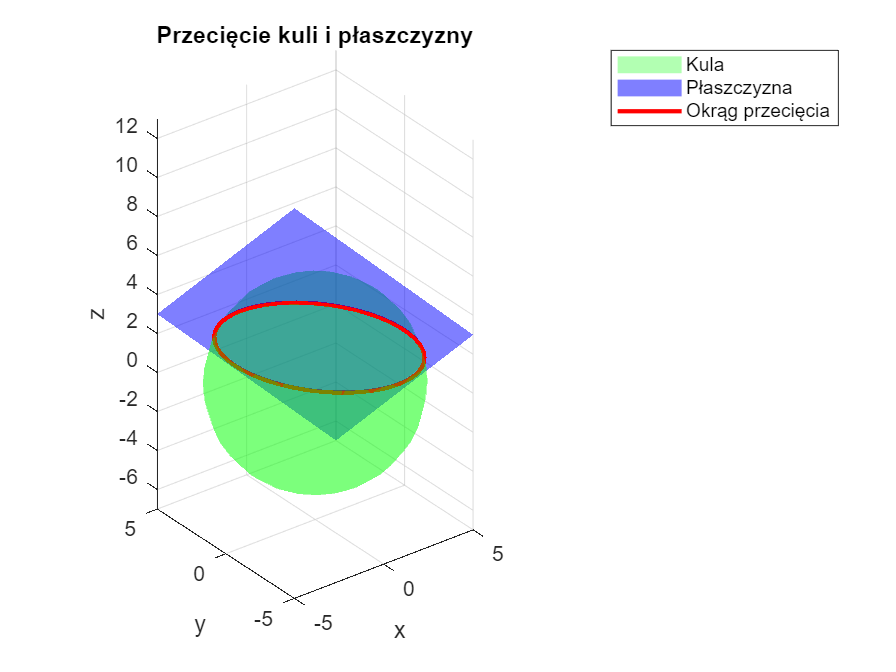

%% Tworzenie siatki dla kuli
[x_sphere, y_sphere, z_sphere] = sphere(20); % Siatka dla kuli
x_sphere = R * x_sphere;
y_sphere = R * y_sphere;
z_sphere = R * z_sphere;

% Tworzenie siatki dla płaszczyzny
[x_plane, y_plane] = meshgrid(-R:0.5:R, -R:0.5:R);
z_plane = (-D - A * x_plane - B * y_plane) / C;

%% Rysowanie kuli, płaszczyzny i okręgu przecięcia
figure;
% Rysowanie kuli
surf(x_sphere, y_sphere, z_sphere, 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceColor', 'green');
hold on;

% Rysowanie płaszczyzny
surf(x_plane, y_plane, z_plane, 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'FaceColor', 'blue');

% Rysowanie okręgu przecięcia
plot3(circle_x, circle_y, circle_z, 'r-', 'LineWidth', 2);

% Ustawienia osi i opis
xlabel('x');
ylabel('y');
zlabel('z');
title('Przecięcie kuli i płaszczyzny');
legend('Kula', 'Płaszczyzna', 'Okrąg przecięcia');
axis equal;
grid on;
view(3);
hold off;

Symboliczne zmienne umożliwiają rozwiązywanie równań i nierówności bez przybliżeń.

Symbolic Math Toolbox pozwala na obliczanie pochodnych i całek w sposób analityczny a także pozwala na obliczanie transformat Laplace’a i Fouriera.

**Przykłady zastosowania**

- **Analiza wyrażeń matematycznych**: Symboliczne podejście jest przydatne, gdy chcemy przeanalizować dokładne właściwości funkcji lub równań, np. obliczenie miejsc zerowych wielomianu lub wyznaczenie asymptot funkcji.

- **Równania różniczkowe**: Symboliczne zmienne umożliwiają analityczne rozwiązywanie równań różniczkowych, co jest istotne w modelowaniu matematycznym, automatyce i robotyce.

- **Optymalizacja i analiza funkcji w naukach inżynieryjnych**: Symbolic Math Toolbox jest przydatny w analizie systemów dynamicznych, obliczeniach związanych z układami sterowania oraz w przetwarzaniu sygnałów.

- WYZNACZENIE OBSZARU ROBOCZEGO DLA MANIPULATORA (OGRANICZENIE PRZESTRZENI ROBOCZEJ)

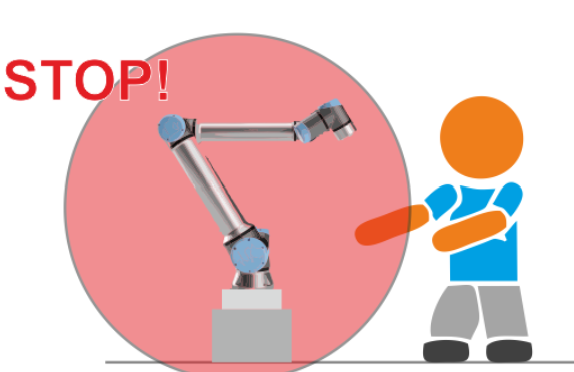

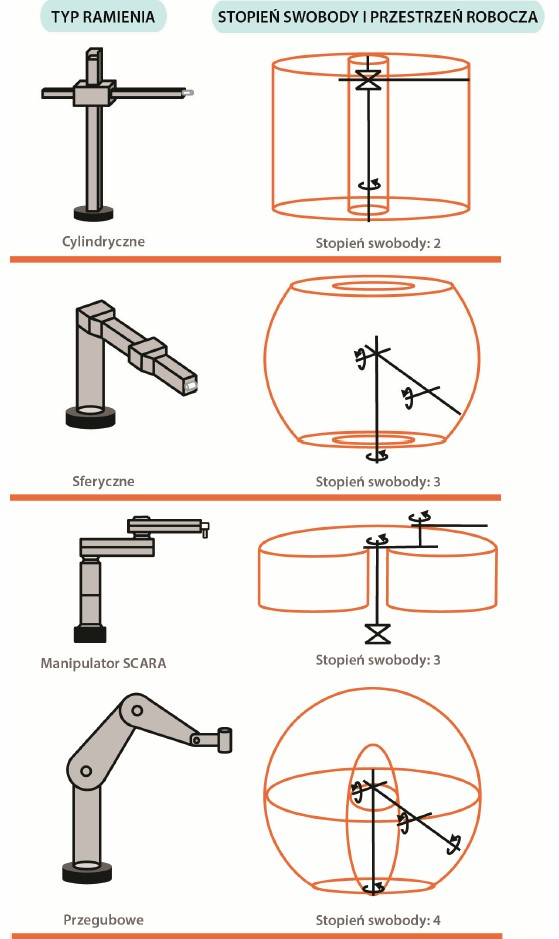

Więcej informacji w szkoleniu online:

[https://matlabacademy.mathworks.com/details/introduction-to-symbolic-math-with-matlab/symbolic](https://matlabacademy.mathworks.com/details/introduction-to-symbolic-math-with-matlab/symbolic)